**Liquid Heat Capacity Correlation**

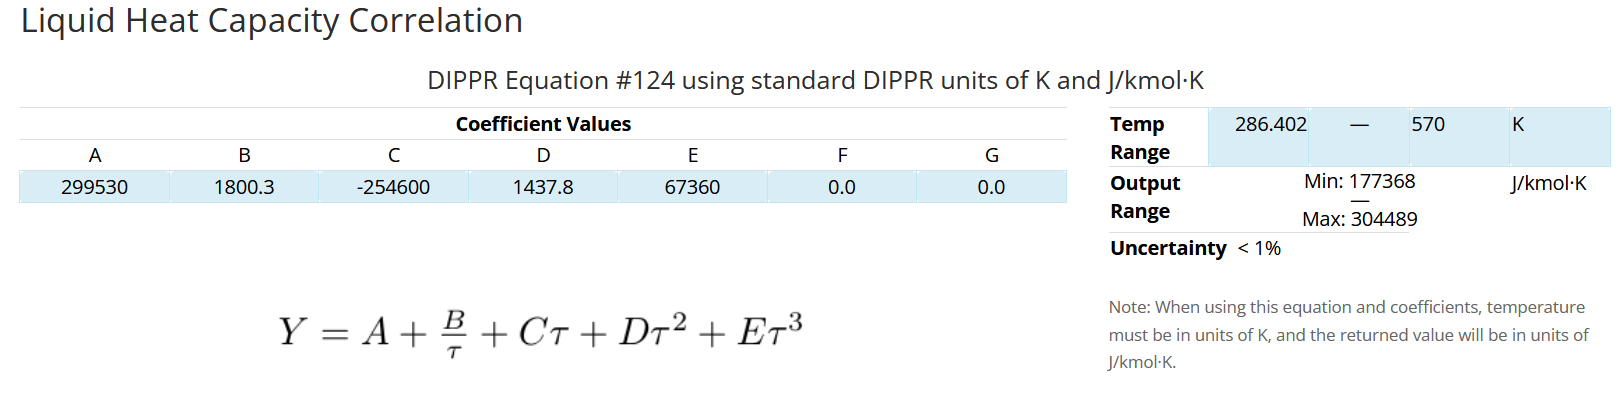

function Y = Cp_xil_liq(T_K)

TKmax = 570;
TKmin = 286.402;

idxmax = find(T_K >= TKmax);
T_K(idxmax) = TKmax;

idxmin = find(T_K <= TKmin);
T_K(idxmin) = TKmin;

if ~isempty(idxmin)
    warning('A propriedade está a ser extrapolada para baixo!!')
elseif ~isempty(idxmax)
      warning('A propriedade está a ser extrapolada para cima!!')
end


Tc = 343.05 + 273.15; % K
tau = 1 - T_K/Tc;
A=299530;
B=1800.3;
C=-254600;
D=1437.8;
E=67360;
% F=0.0;
% G= 0.0;
 	 	 	
Y = A + B./tau + C*tau + D*tau.^2 + E*tau.^3; %  J/kmol·K
%Y = Y/1000/1000; % kJ/mol/K
end